# Sprawozdanie z laboratorium 10

Karolina Piotrowska

## Wstęp

Celem laboratorium było wyznaczenie parametrów modelu rzeczywistego obiektu regulacji o następującej odpowiedzi skokowej:

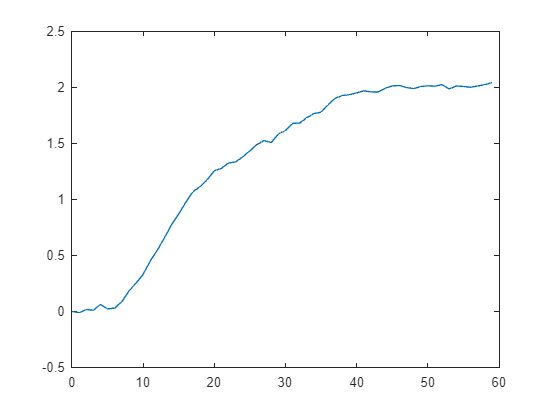

load obiekt;
t = 0:59;
plot(t, y);

Obiekt ten może zostać sprowadzony do następujących modeli:

- obiekt inercyjny I-go rzędu z opóźnieniem

                        

- obiekt inercyjny II-go rzędu z opóźnieniem

                        

- obiekt inercyjny rzędu III, IV, V lub VI

                          

## Rozwiązanie 

### Model A wyznaczony metodą 2.1

load obiekt;

theta = 7.15;
k = 2.125;
T = 15.05;
t = 0:59;

modelA = tf([0 k], [T 1]);
set(modelA, 'outputDelay', theta);
yModel = step(modelA, t);
e = y - yModel;
RMS = sum(e.^2)/length(e)

RMS = 0.0015

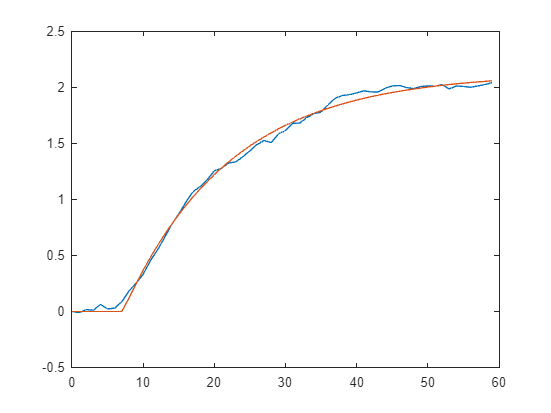


plot(t, y, t, yModel);

### Model A wyznaczony metodą 2.4

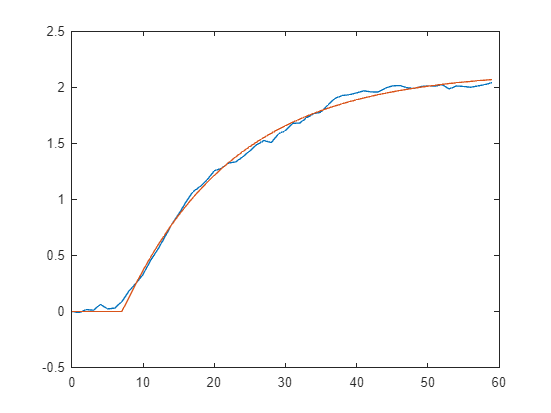

parametry =     2.1422   15.4255    7.0972


blad = 0.0015

[parametry, blad] = fminsearch('ident',[k, T, theta])

### Model B wyznaczony metodą 2.4

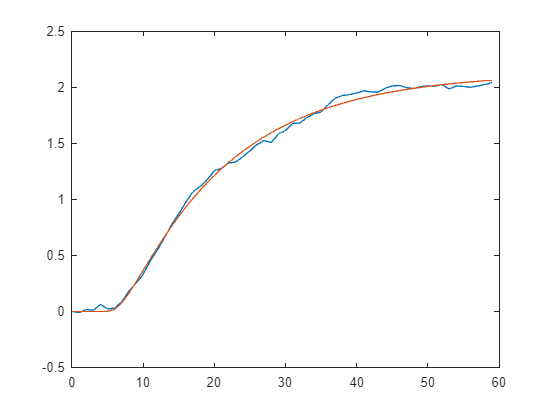

parametry =     2.1292   14.8405    2.0541    5.2836


blad = 0.0013

[parametry, blad] = fminsearch('ident2',[k, T, T, theta])

### Model B wyznaczony metodą 2.3

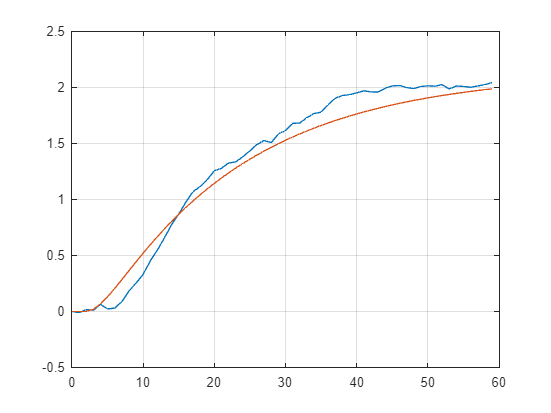

load obiekt;

theta1=2.0541;
k1=2.1292;
T1=20.2428;
T2=2.2492;
t1=0:59;

modelB3=tf([0 0 k1], [T1*T2 T1+T2 1]);
set(modelB3, 'outputDelay', theta1);
yModel1=step(modelB3,t1);
plot(t1,y,t1,yModel1);
grid on;


e1=y-yModel1;
RMS=sum(e1.^2)/length(e1)

RMS = 0.0138

### Model C wyznaczony metodą 2.4s

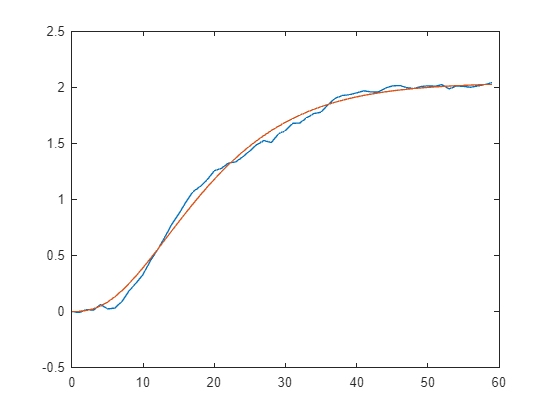

parametry =     2.0396    6.6553


blad = 0.0024

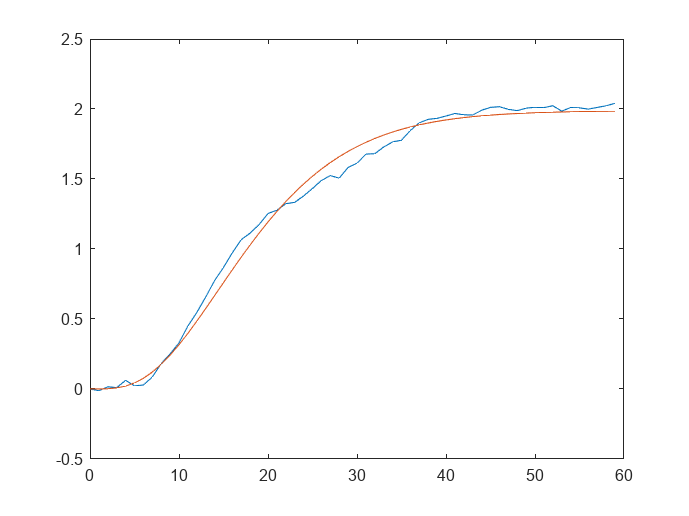

parametry =     1.9880    4.7882


blad = 0.0040

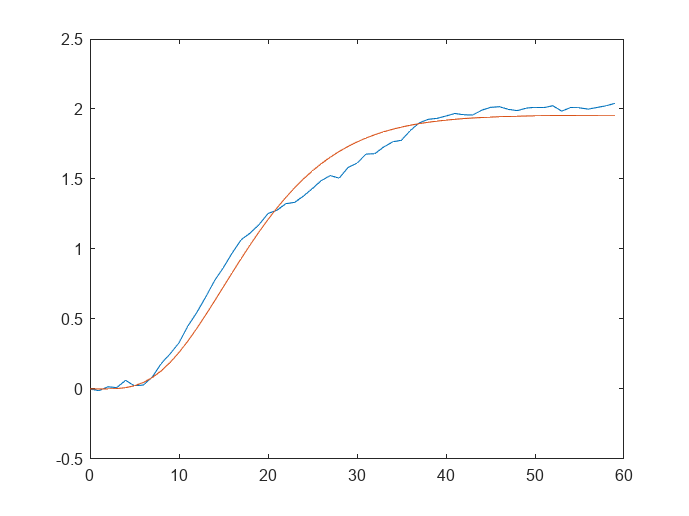

parametry =     1.9567    3.7380


blad = 0.0071

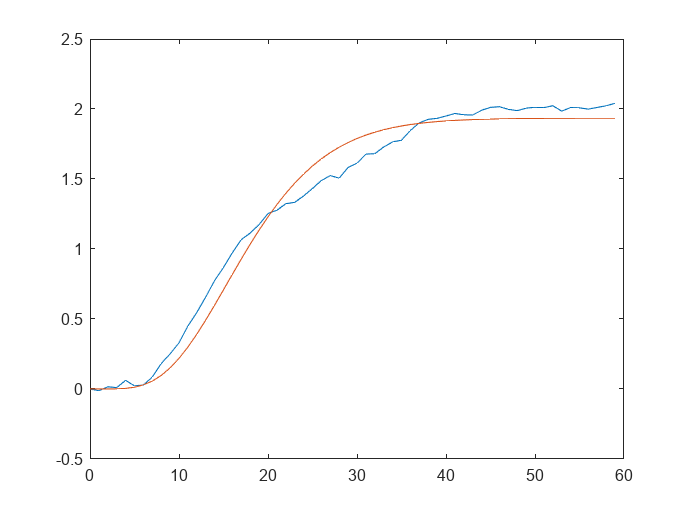

parametry =     1.9347    3.0614


blad = 0.0106

load obiekt;
rzad = [3 4 5 6];
global n;
for i = 1:length(rzad)
    n = rzad(i);
    [parametry, blad] = fminsearch('ident3', [k, T])
end